# Lesson 2: collecting data from multiple files

Data files: [https://drive.google.com/file/d/1kwzy0HeYRou9QeiHVmkFYbIildTKhpWc/view?usp=sharing](https://drive.google.com/file/d/1kwzy0HeYRou9QeiHVmkFYbIildTKhpWc/view?usp=sharing)

Function for getting the images: [https://drive.google.com/file/d/1BcNXAMLo7hLsOLZH2Z2olaXHmey7TGTU/view?usp=sharing](https://drive.google.com/file/d/1BcNXAMLo7hLsOLZH2Z2olaXHmey7TGTU/view?usp=sharing) 

Each file name has the following structure: geometry name + _P + period + _H + height.

periods = 300:50:400;
heights = 600:100:1000;
geom_names = {'post','post_inverted','mid_corner_circ',...
    'mid_corner_circ_inverted','4ellipses','4ellipses_inverted',...
    'cross','cross_inverted','4bars_rounded','4bars_rounded_inverted',...
    '2posts','2posts_inverted'};

Each file has a `data` matrix, size number of wavelength times number of geometries, vector of wavelength values and cell array of function handles that generate the images.

### Task 1. Get all the datafile names as a cell array using ls.

On Unix

list = ls('datafiles/simdata/*.mat'); % note file path may vary
list = split(list);
list(end) = []; % delete final empty array

On Windows

list = ls('datafiles/simdata/*.mat'); % note file path may vary
% add additional padding with spaces
list = [list, repmat(' ',size(list,1),1)];
list = list.';
list = list(:).';
list = split(list, ' ');
% remove empty cells
list(cellfun(@isempty, list)) = [];
% delete '.' and '..' cells if needed
list(1:2) = []; % or list = list(3:end);

Or another simpler way for Windows

list = ls('datafiles/simdata/*.mat'); % note file path may vary
list = num2cell(list, 2); % put each row into a cell
list = cellfun(@strip, list, 'UniformOutput', false); % remove extra whitespaces
% this cellfun is totally equivalent to the following loop
% for i = 1:length(list)
%     list{i} = strip(list{i});
% end

### Task 2. Collect all the data for different paramters into one large matrix glued along the 'geometry' dimension.

data = [];
for i = 1:length(list)
    f = load(strip(list{i})); % extra strip for safety
    data = [data, f.data]; % ignore the warning
end

### Task 2a. For speed pre-load all the files into memory.

### Task 3. Plot phase scatter plots for all the data as in Lesson 1.

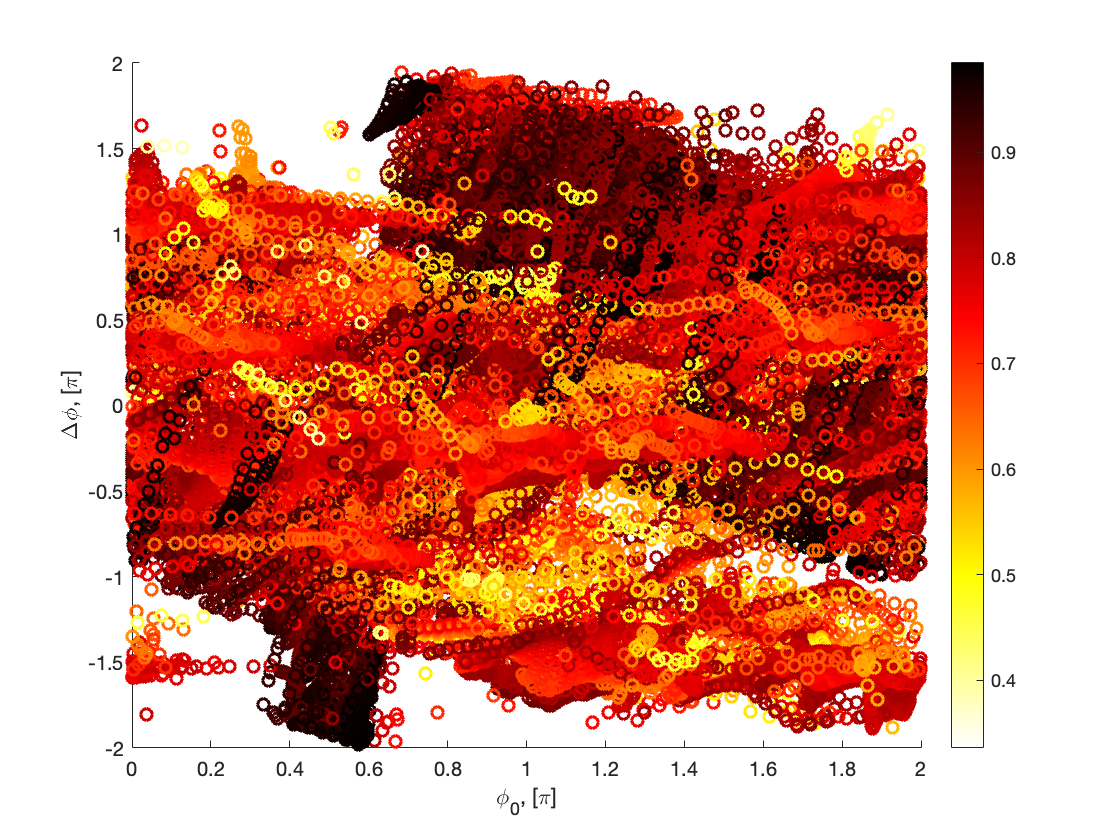

% Same as in Lesson 1 (Tasks 2 and 3), but define phase as angle of data and amp as abs of
% data.
wavelength = f.wl;
phase = mod(angle(data),2*pi); % same as atan(imag(data)./real(data))
amp = abs(data); % same as sqrt(real(data).^ + imag(data).^2)
[~, mid] = min(abs(wavelength - mean(wavelength)));
phi0 = phase(mid,:);
delta_phi = diff(phase([end 1],:));
ave = mean(amp.^2);

figure; scatter(phi0/pi, delta_phi/pi, 36, ave, "LineWidth", 1.5); 
colormap(flipud(hot)); colorbar
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

Show only high tranmission entries

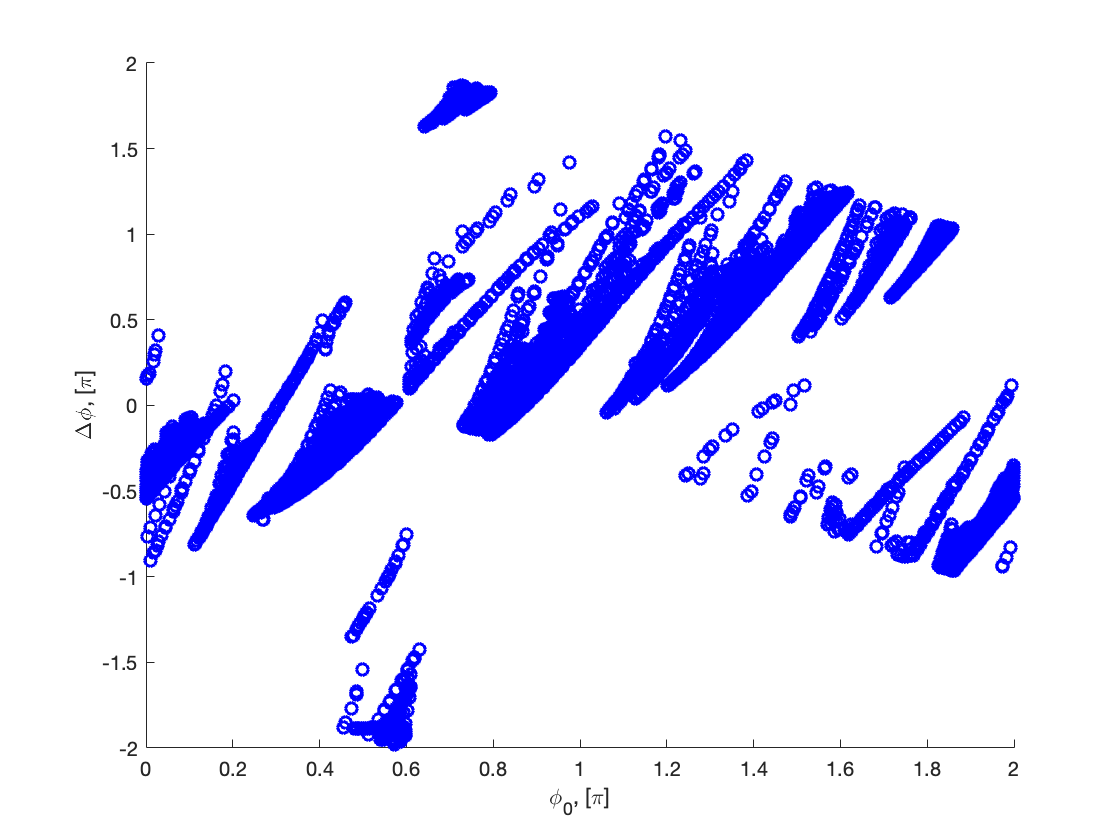

idx = ave > .97;
figure; scatter(phi0(idx)/pi, delta_phi(idx)/pi, 36, 'b', "LineWidth", 1.5); 
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

### Task 4. Make a scatter plot where in red we have 'non-iverted' geomtries, in blue -- 'inverted' ones.

% Hint: to filter out inverted geometries, in the for loop from Task 2 use
% contains(list{i},'inverted'). This checks if the filename contains the
% word "inverted". If it does, record the data to something like
% data_inverted array, instead of data.
% Hint 2: make same steps as in Task 3 (amp not needed, as color will be
% fixed)
data = [];
data_inverted = [];
for i = 1:length(list)
    f = load(strip(list{i})); % extra strip for safety
    if contains(list{i},'inverted')
        data_inverted = [data_inverted, f.data]; % ignore the warning
    else
        data = [data, f.data]; % ignore the warning
    end
end
wavelength = f.wl;
phase = mod(angle(data),2*pi); % same as atan(imag(data)./real(data))
phase_inverted = mod(angle(data_inverted),2*pi);
amp = abs(data); % same as sqrt(real(data).^ + imag(data).^2)
amp_inverted = abs(data_inverted);
[~, mid] = min(abs(wavelength - mean(wavelength)));
phi0 = phase(mid,:);
delta_phi = diff(phase([end 1],:));
ave = mean(amp.^2);
phi0_inverted = phase_inverted(mid,:);
delta_phi_inverted = diff(phase_inverted([end 1],:));
ave_inverted = mean(amp_inverted.^2);

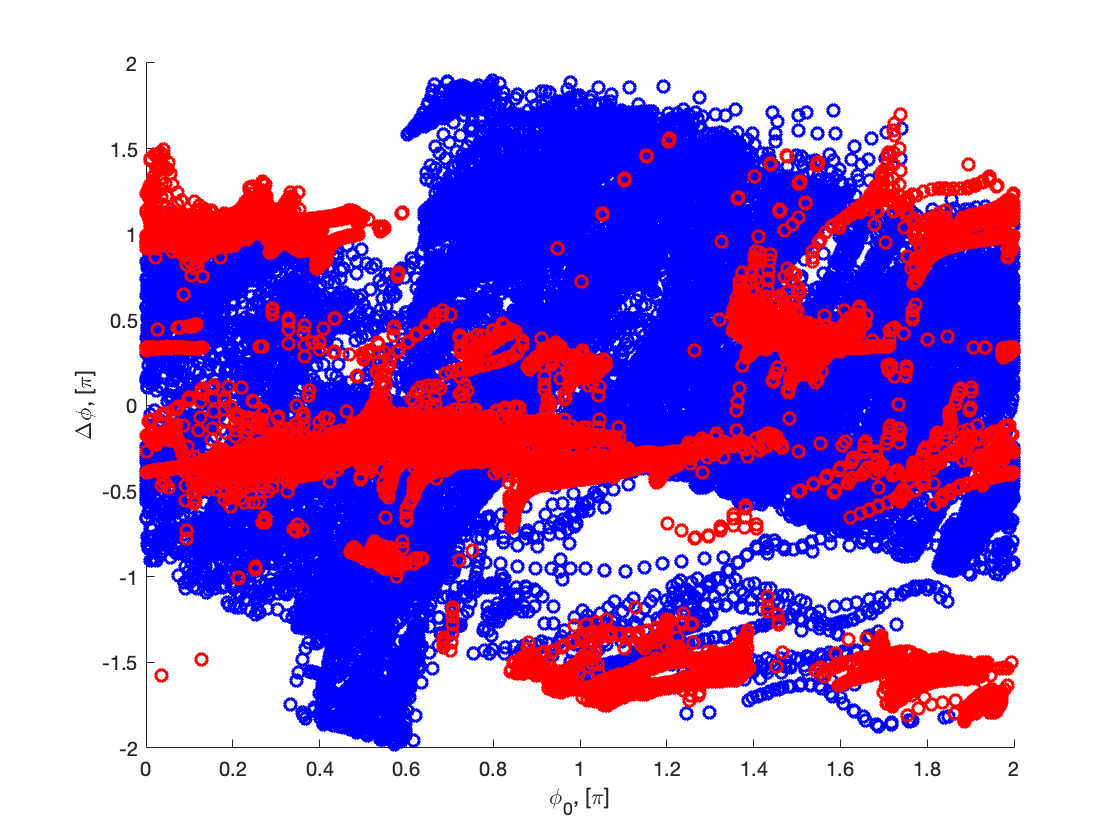

max_ave = .8;
idx = ave > max_ave;
idx2 = ave_inverted > max_ave;
figure
scatter(phi0(idx)/pi, delta_phi(idx)/pi, 36, 'b', "LineWidth", 1.5); 
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')
hold on
scatter(phi0_inverted(idx2)/pi, delta_phi_inverted(idx2)/pi, 36, 'r', "LineWidth", 1.5); 
xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')

### Task 5. In a seprate subplots for inverted and non-inverted, colorcode data by height for a fixed period. Later, make a separate plot for each period. 

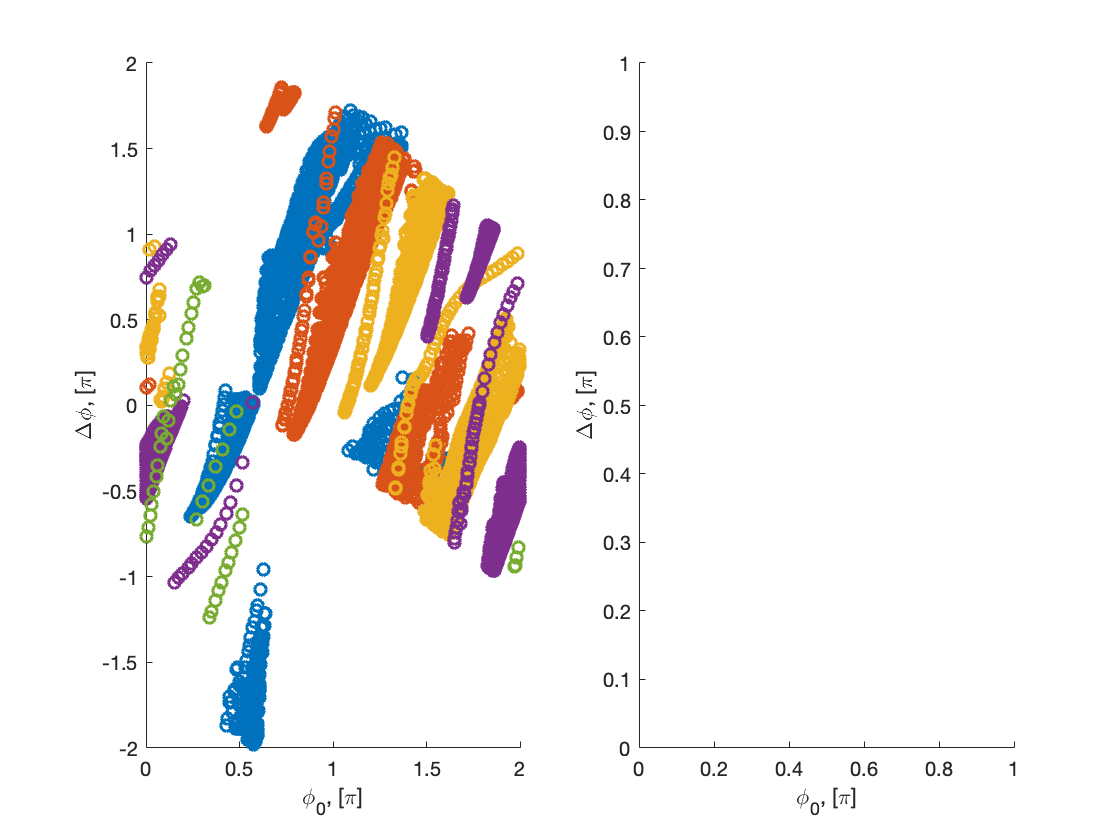

% In this task, the loop will be a bit different
period = periods(1);
figure
for hcurr = heights    
    data = [];
    data_inverted = [];
    for iname = 1:length(geom_names)
        % folder path depends on your directory structure
        fname = ['datafiles/simdata/',geom_names{iname}, '_P', num2str(period), '_H', num2str(hcurr),'.mat'];
        if exist(fname,'file')
            f = load(fname); 
        end
        if contains(fname,'inverted')
            data_inverted = [data_inverted, f.data];
        else
            data = [data, f.data];
        end
    end
    
    phase = mod(angle(data),2*pi); % same as atan(imag(data)./real(data))
    phase_inverted = mod(angle(data_inverted),2*pi);
    amp = abs(data); % same as sqrt(real(data).^ + imag(data).^2)
    amp_inverted = abs(data_inverted);
    [~, mid] = min(abs(wavelength - mean(wavelength)));
    phi0 = phase(mid,:);
    delta_phi = diff(phase([end 1],:));
    ave = mean(amp.^2);
    phi0_inverted = phase_inverted(mid,:);
    delta_phi_inverted = diff(phase_inverted([end 1],:));
    ave_inverted = mean(amp_inverted.^2);
    % what we want
%     [phi0,delta_phi,ave] = myfun(data);
%     [phi0_inverted,delta_phi_inverted,ave_inverted] = myfun(data_inverted);
    max_ave = .9;
    idx = ave > max_ave;
    idx2 = ave_inverted > max_ave;
    
    subplot(1,2,1)
    scatter(phi0(idx)/pi, delta_phi(idx)/pi, 36, "LineWidth", 1.5); 
    xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')
    hold on
    subplot(1,2,2)
    scatter(phi0_inverted(idx2)/pi, delta_phi_inverted(idx2)/pi, 36, "LineWidth", 1.5); 
    xlabel('\phi_0, [\pi]'); ylabel('\Delta\phi, [\pi]')
end

### Task 6. Create a new variable "volume fraction" and use it as color coding for the scatter plots (inverted and non-inverted separately).